# Scatter plots

## Read data

Use the function load. Filename: cardata.mat

load('cardata.mat');

## Create figure object

Use the function figure

fig1 = figure();

## Create scatter plot

Use the function scatter to plot MPG vs Horsepower. Also, get a handle to the axes object using CurrentAxes property of the figure object.

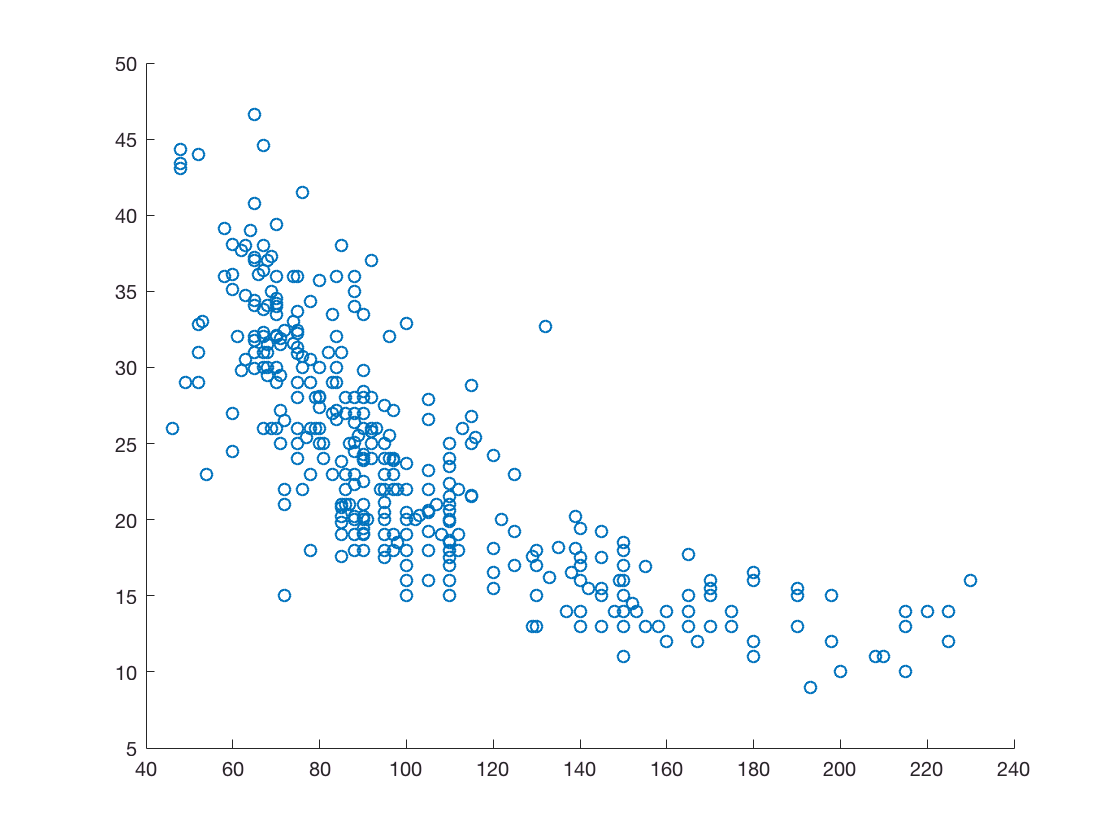

sc1 = scatter(Horsepower, MPG);

ax1 = fig1.CurrentAxes;

## Look up scatter

help scatter

 scatter Scatter/bubble plot.
    scatter(X,Y,S,C) displays colored circles at the locations specified
    by the vectors X and Y (which must be the same size).  
 
    S determines the area of each marker (in points^2). S can be a
    vector the same length a X and Y or a scalar. If S is a scalar, 
    MATLAB draws all the markers the same size. If S is empty, the
    default size is used.
    
    C determines the colors of the markers. When C is a vector the
    same length as X and Y, the values in C are linearly mapped
    to the colors in the current colormap. When C is a 
    length(X)-by-3 matrix, it directly specifies the colors of the  
    markers as RGB values. C can also be a color string. See ColorSpec.
 
    scatter(X,Y) draws the markers in the default size and color.
    scatter(X,Y,S) draws the markers at the specified sizes (S)
    with a single color. This type of graph is also known as
    a bubble

## Add Accelaration values to marker size

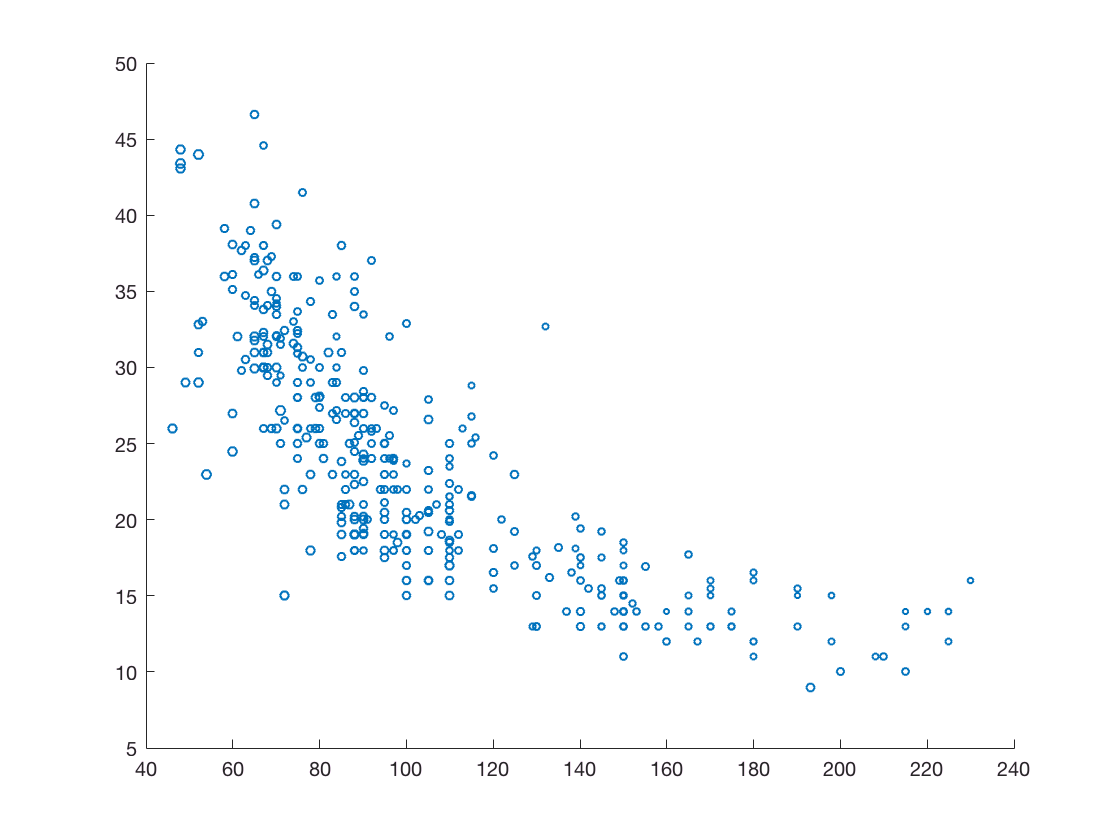

sc1 = scatter(Horsepower, MPG, Acceleration);

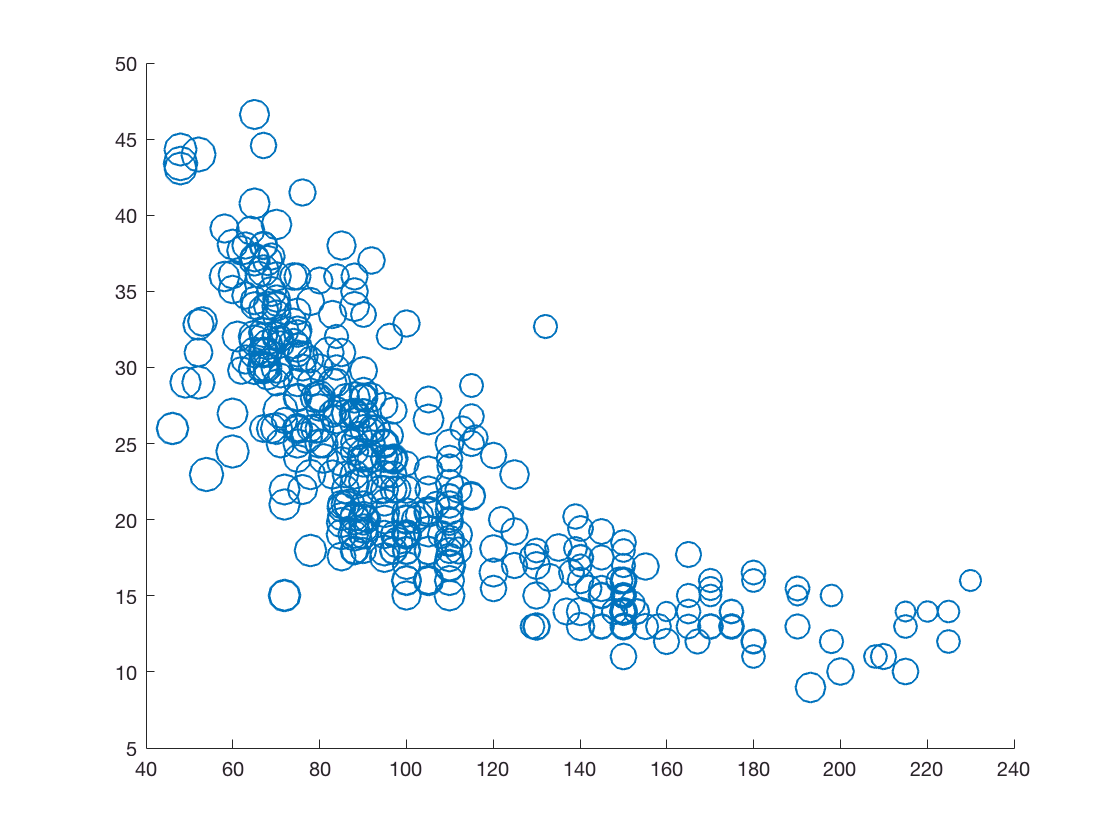

sc1 = scatter(Horsepower, MPG, Acceleration*12);

## Add Weight as a colormap

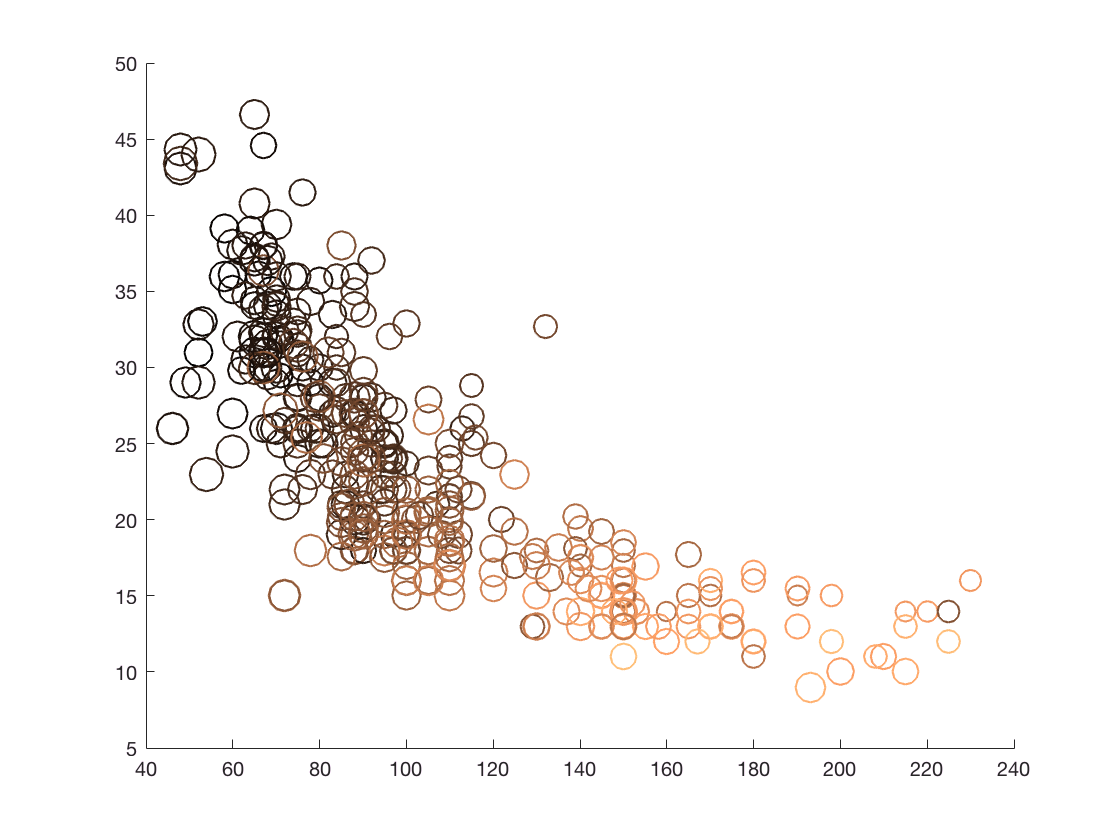

sc1 = scatter(Horsepower, MPG, Acceleration*12, Weight);
colormap('copper');

## Modify axis properties

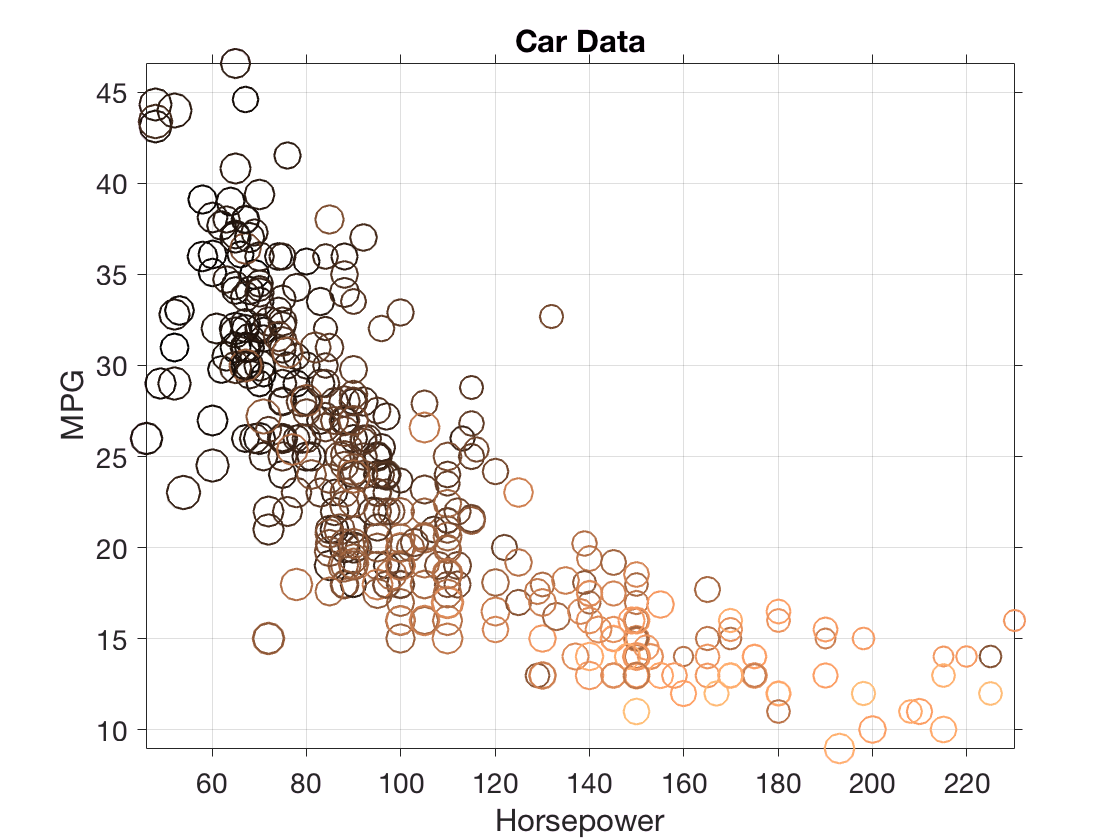

ax1.FontSize = 14;
ax1.XLabel.String = 'Horsepower'; 
ax1.XLabel.FontSize = 16;
ax1.YLabel.String = 'MPG'; 
ax1.YLabel.FontSize = 16;
ax1.Box = 'on';
ax1.TickDir = 'out';
ax1.Title.String = 'Car Data';
axis tight;
grid on;

## Modify marker properties

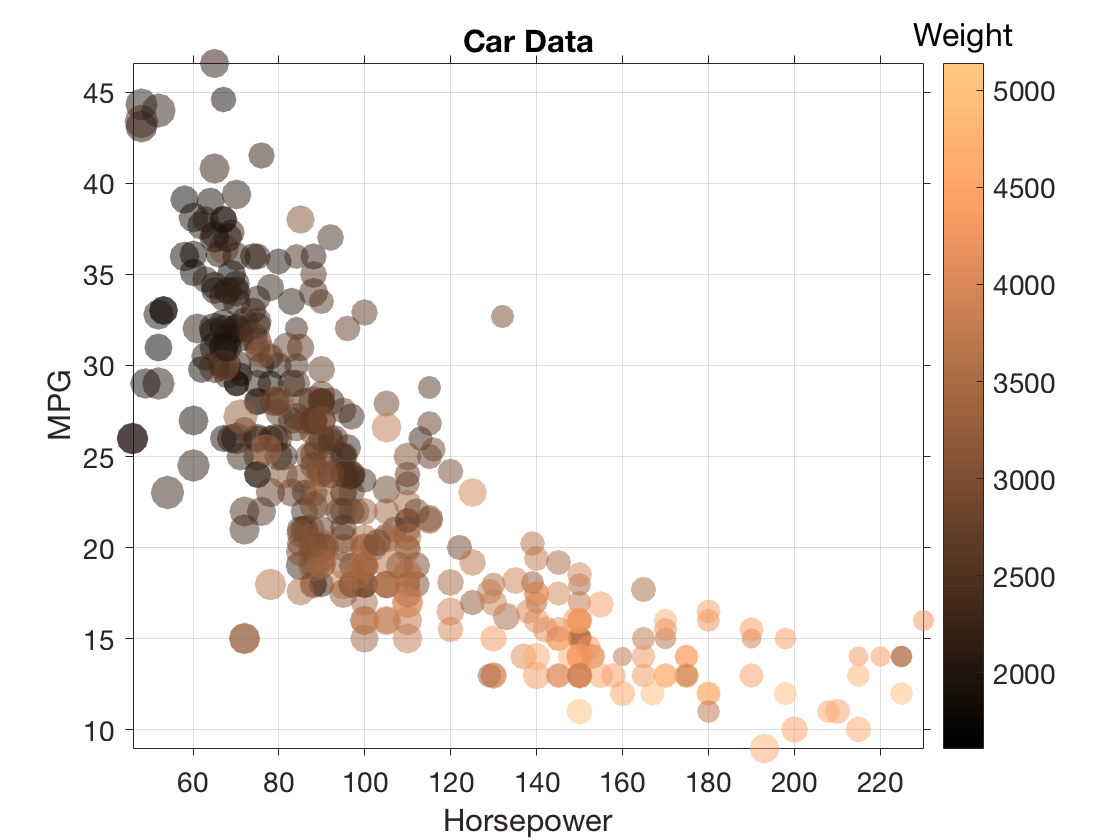

sc1.MarkerFaceColor = 'flat';
sc1.MarkerEdgeColor = 'none';
sc1.MarkerFaceAlpha = 0.5;
cbar = colorbar();
cbar.Title.String = 'Weight';
cbar.Title.FontSize = 16;
cbar.FontSize = 14;